%% 한개의 해석지점
copperWinding_sigma=1/1.724E-08  % [S/m]


AC Conductor Loss Split

# AC Loss Calculation

## 1. MotorCAD

for mcadNumber=1:3
mcad(mcadNumber)=callMCAD
end

### 1. 한속도별 간단한 case

speedList=[1000]
mcadNumber=2
hybridACLossPerRPM=struct()

% 속도별로 추출 (고정전류위상각)
speedIndex=1
% for speedIndex=1:length(speedList)
for mcadNumber=1:1
mcad(mcadNumber).SetVariable('HybridAdjustmentFactor_ACLosses',1)
mcad(mcadNumber).SetVariable('ShaftSpeed',speedList(speedIndex))
mcad(mcadNumber).DoMagneticCalculation
ModelPerMcad(mcadNumber).hybridACLossPerRPM(speedIndex).hybridACLossStr=devCalcHybridACLossModelwithSlotB(mcad(mcadNumber))
end
% end

PacByMcadTotalValuesScale = arrayfun(@(x) x.hybridACLossStr.byMcad.PacTotal, hybridACLossPerRPM);
PacCalcTotalValuesScale   = arrayfun(@(x) x.hybridACLossStr.calc.PacTotal, hybridACLossPerRPM)  ;

omega=elec2mech(omegaE,4)
freq2rpm(omega2freq(omega))

omegaE=rpm2OmegaE(1000,4)
freq2omega(60)

### 2.[Done4MCAD]Improved Method vs Original Method

Hybrid AC Loss Method

Hairpin AC loss location Method

hybrid AC Loss High Frequency Scaling Correction Method

mcad(1).SetVariable('ACLossHighFrequencyScaling_Method',1)  % 1: Improved Method  0: Original Method
mcad(1).SetVariable('HairpinACLossLocationMethod',1)  % 1: Improved Method  0: Original Method
mcad(1).SetVariable('HybridACLossMethod',1)  % 1: Improved Method  0: Original Method
% Hybrid Method 3개
% Detail Method 1개? 
% 속도 리스트
speedList = [500, 1000, 2000, 4000, 8000, 15000];
speedList=[500, 1000 ,2000,4000,8000,15000]
% 모든 경우의 수에 대한 결과를 저장할 구조체 배열 초기화
simulationResults = struct();

% 경우의 수 인덱스
index = 1;

tic 
% 각 메소드에 대한 설정 (0: Original, 1: Improved)
for ACLossHighFrequencyScaling_Method = 0:1
    for HairpinACLossLocationMethod = 0:1
        for HybridACLossMethod = 0:1
            % 속도별로 추출
            for speedIndex = 1:length(speedList)
                % MCAD 설정
                mcad(1).SetVariable('ACLossHighFrequencyScaling_Method', ACLossHighFrequencyScaling_Method);
                mcad(1).SetVariable('HairpinACLossLocationMethod', HairpinACLossLocationMethod);
                mcad(1).SetVariable('HybridACLossMethod', HybridACLossMethod);
                
                % 속도 설정 및 시뮬레이션 실행
                mcad(1).SetVariable('ShaftSpeed', speedList(speedIndex));
                mcad(1).DoMagneticCalculation;
                
                % 시뮬레이션 결과 저장
                simulationResults(index).ACLossHighFrequencyScaling_Method = ACLossHighFrequencyScaling_Method;
                simulationResults(index).HairpinACLossLocationMethod = HairpinACLossLocationMethod;
                simulationResults(index).HybridACLossMethod = HybridACLossMethod;
                simulationResults(index).Speed = speedList(speedIndex);
                % 여기에 다른 필요한 결과 데이터를 저장하는 코드 추가
                simulationResults(index).hybridACLossStr=devCalcHybridACLossModelwithSlotB(mcad(2))
                index = index + 1;
            end
        end
    end
end
toc

#### Arrayfun 조회 

% simulationResults 구조체 배열 예시
% simulationResults = struct('Speed', {1000, 2000, 3000, 1000}, 'Method', {'Method1', 'Method2', 'Method1', 'Method2'}, ...);

% 조회하고자 하는 속도 값
targetSpeed = 1000;

% 속도가 targetSpeed와 일치하는지 여부를 판별하여 논리적 배열 생성
isTargetSpeed = arrayfun(@(x) x.Speed == targetSpeed, simulationResults);

% 논리적 인덱싱을 사용하여 해당 속도의 결과만 필터링
filteredResults = simulationResults(isTargetSpeed);

% 필터링된 결과 출력
disp(filteredResults);



% 필터링 조건: ACLossHighFrequencyScaling_Method, HairpinACLossLocationMethod, HybridACLossMethod 모두 1
filteredResults = simulationResults(arrayfun(@(x) ...
    x.ACLossHighFrequencyScaling_Method == 1 && ...
    x.HairpinACLossLocationMethod ==  1&& ...
    x.HybridACLossMethod == 1, ...
    simulationResults));


% filteredResults 구조체 배열에서 PacTotal 값 추출
Speed = arrayfun(@(x) x.Speed, filteredResults);
PacByMcadTotalValues = arrayfun(@(x) x.hybridACLossStr.byMcad.PacTotal, filteredResults);
PacCalcTotalValues = arrayfun(@(x) x.hybridACLossStr.calc.PacTotal, filteredResults);

% save("KDHPC2024WorkSpace4ACLossCompMCAD.mat","PacCalcTotalValues","PacByMcadTotalValues","Speed","simulationResults","hybridACLossPerRPM","PacByMcadTotalValuesScale","PacCalcTotalValuesScale")


#### Plot

% PacTotal 값에 대한 그래프 그리기
plot(Speed,PacByMcadTotalValues);
xlabel('Index'); % 인덱스 또는 다른 적절한 라벨
ylabel('PacTotal'); % 적절한 단위를 포함한 라벨
title('PacTotal Values from filteredResults');
grid on;
figure(2)
plot(Speed,PacCalcTotalValues);
xlabel('Index'); % 인덱스 또는 다른 적절한 라벨
ylabel('PacCalcTotal'); % 적절한 단위를 포함한 라벨
title('PacTotal Values from filteredResults');
grid on;


비율 비교

- 속도 4배씩 (제곱비) 확인



% 속도별 차이
index=1
divRatio=[]
for i=length(PacCalcTotalValues):-1:2
divRatio(index)=PacCalcTotalValues(i)./PacCalcTotalValues(i-1)
index=index+1
end

%% Calc와 MCAD차이 비율
RatioCalc4Model.Model1.value=PacByMcadTotalValues/1000./PacCalcTotalValues
RatioCalc4Model.Model2.value=PacByMcadTotalValuesScale/1000./PacCalcTotalValuesScale
RatioCalc4Model.Model3.value=PacByMcadTotalValuesScale/1000./PacCalcTotalValuesScale

[~,RatioCalc4Model.Model1.Path]=mcad(1).GetVariable("CurrentMotFilePath_MotorLAB")
[~,RatioCalc4Model.Model2.Path]=mcad(2).GetVariable("CurrentMotFilePath_MotorLAB")
[~,RatioCalc4Model.Model3.Path]=mcad(3).GetVariable("CurrentMotFilePath_MotorLAB")


## 2. JMAG AC Loss 

### Transient AC Loss

JMAG=callJmag
app=JMAG
app.GetAppDir
app.Show
Model=app.GetCurrentModel
Model.GetName
NumStudies=Model.NumStudies

JMAGStudyTable=devgetJMAGStudyListTable(Model)
filteredJMAGStudyTable=filterJMAGStudyTableByStudyName(JMAGStudyTable,'Sinusoidal_1')

StepData = defSinglePeriodFromStudyTable(filteredJMAGStudyTable)

EndTime     =StepData.EndTime;
StepDivision=StepData.StepDivision;
xTime=(0:(EndTime/StepDivision):EndTime)';

#### ResultTable

StudySin=filteredJMAGStudyTable.StudyObj
StudySin.IsValid
StudySin.GetName
LossStudyResultTableObj=StudySin.GetResultTable

% Plot
ResultDataStruct = getJMagResultDatas(LossStudyResultTableObj, 'Joule Loss: W')
AllResultDataStruct = getJMagResultDatas(LossStudyResultTableObj)

AllResultDataStruct.EndTime=EndTime;
AllResultDataStruct.StepDivision=StepDivision;
WireLossTable=filterTablewithString(ResultDataStruct.dataTable,'/Wire');



#### Plot JMAG ResultTable

plotTransientTable(WireLossTable,StepData)
plotJMAGResultDataStruct(AllResultDataStruct,StepData)

#### Multi PurPose Export - Mesh Export

WorkDir=JMAG.GetProjectPath


### [TC]Designer Mesh (Element & Node추출)

devgetMeshData함수 사용, 위치는 추출불가능한듯

field 데이터와 element, Node 할당

% StudySin=app.GetCurrentStudy
% StudySin.IsValid
% Model=app.GetModel(0)
% app.View
%  sel=devTempCreateDesignerSelection(app)
% 
%  i_Stator_OD=110
% selectAirByWorldPosSOD(i_Stator_OD,app)
% sel.FaceID


% sel.IsValid

devgetMeshData

## [TB]Jquery mesh Mfile

opengmsh
JFT047FeedbackControl
% A = area(msh)
emagE = createpde("electromagnetic")
nodes=1000*msh.POS(:,1:2)';
elements=msh.TRIANGLES(:,1:3)';

centerfig()
hold on
ax=gca

ax.GridAlpha = 0.05
geometryFromMesh(emagE,nodes,elements);
a=pdeplot(emagE.Mesh.Nodes, emagE.Mesh.Elements);

a.Color=[0.90,0.90,0.90]  % grey
area(emagE.Mesh,2)
centerfig()
pdegplot(emagE,"CellLabels","on","FaceAlpha",0.5,FaceLabels="on")



## [TB]JqueryElement

#### [TB]JqueryB Export (JQuery)

### Import B

% 가져오기 옵션을 설정하고 데이터 가져오기
opts = delimitedTextImportOptions("NumVariables", 185);

% 범위 및 구분 기호 지정
opts.DataLines = [3, Inf];
opts.Delimiter = ",";

% 열 이름과 유형 지정
opts.VariableNames = ["ElementID", "Step541_X", "Step542_X", "Step543_X", "Step544_X", "Step545_X", "Step546_X", "Step547_X", "Step548_X", "Step549_X", "Step550_X", "Step551_X", "Step552_X", "Step553_X", "Step554_X", "Step555_X", "Step556_X", "Step557_X", "Step558_X", "Step559_X", "Step560_X", "Step561_X", "Step562_X", "Step563_X", "Step564_X", "Step565_X", "Step566_X", "Step567_X", "Step568_X", "Step569_X", "Step570_X", "Step571_X", "Step572_X", "Step573_X", "Step574_X", "Step575_X", "Step576_X", "Step577_X", "Step578_X", "Step579_X", "Step580_X", "Step581_X", "Step582_X", "Step583_X", "Step584_X", "Step585_X", "Step586_X", "Step587_X", "Step588_X", "Step589_X", "Step590_X", "Step591_X", "Step592_X", "Step593_X", "Step594_X", "Step595_X", "Step596_X", "Step597_X", "Step598_X", "Step599_X", "Step600_X", "Step601_X", "Step602_X", "Step603_X", "Step604_X", "Step605_X", "Step606_X", "Step607_X", "Step608_X", "Step609_X", "Step610_X", "Step611_X", "Step612_X", "Step613_X", "Step614_X", "Step615_X", "Step616_X", "Step617_X", "Step618_X", "Step619_X", "Step620_X", "Step621_X", "Step622_X", "Step623_X", "Step624_X", "Step625_X", "Step626_X", "Step627_X", "Step628_X", "Step629_X", "Step630_X", "Step631_X", "Step632_X", "Step633_X", "Step634_X", "Step635_X", "Step636_X", "Step637_X", "Step638_X", "Step639_X", "Step640_X", "Step641_X", "Step642_X", "Step643_X", "Step644_X", "Step645_X", "Step646_X", "Step647_X", "Step648_X", "Step649_X", "Step650_X", "Step651_X", "Step652_X", "Step653_X", "Step654_X", "Step655_X", "Step656_X", "Step657_X", "Step658_X", "Step659_X", "Step660_X", "Step661_X", "Step662_X", "Step663_X", "Step664_X", "Step665_X", "Step666_X", "Step667_X", "Step668_X", "Step669_X", "Step670_X", "Step671_X", "Step672_X", "Step673_X", "Step674_X", "Step675_X", "Step676_X", "Step677_X", "Step678_X", "Step679_X", "Step680_X", "Step681_X", "Step682_X", "Step683_X", "Step684_X", "Step685_X", "Step686_X", "Step687_X", "Step688_X", "Step689_X", "Step690_X", "Step691_X", "Step692_X", "Step693_X", "Step694_X", "Step695_X", "Step696_X", "Step697_X", "Step698_X", "Step699_X", "Step700_X", "Step701_X", "Step702_X", "Step703_X", "Step704_X", "Step705_X", "Step706_X", "Step707_X", "Step708_X", "Step709_X", "Step710_X", "Step711_X", "Step712_X", "Step713_X", "Step714_X", "Step715_X", "Step716_X", "Step717_X", "Step718_X", "Step719_X", "Step720_X", "Step721_X", "PositionX", "PositionY", "PositionZ"];
opts.VariableTypes = ["double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double"];

% 파일 수준 속성 지정
opts.ExtraColumnsRule = "ignore";
opts.EmptyLineRule = "read";

% 데이터 가져오기
Bx2 = readtable("Z:\Thesis\00_Theory_Prof\02_System\JFT047FeedbackControl\Bx.csv", opts);

% 가져오기 옵션을 설정하고 데이터 가져오기
opts2 = delimitedTextImportOptions("NumVariables", 185);

% 범위 및 구분 기호 지정
opts2.DataLines = [3, Inf];
opts2.Delimiter = ",";

% 열 이름과 유형 지정
opts2.VariableNames = ["ElementID", "Step541_X", "Step542_X", "Step543_X", "Step544_X", "Step545_X", "Step546_X", "Step547_X", "Step548_X", "Step549_X", "Step550_X", "Step551_X", "Step552_X", "Step553_X", "Step554_X", "Step555_X", "Step556_X", "Step557_X", "Step558_X", "Step559_X", "Step560_X", "Step561_X", "Step562_X", "Step563_X", "Step564_X", "Step565_X", "Step566_X", "Step567_X", "Step568_X", "Step569_X", "Step570_X", "Step571_X", "Step572_X", "Step573_X", "Step574_X", "Step575_X", "Step576_X", "Step577_X", "Step578_X", "Step579_X", "Step580_X", "Step581_X", "Step582_X", "Step583_X", "Step584_X", "Step585_X", "Step586_X", "Step587_X", "Step588_X", "Step589_X", "Step590_X", "Step591_X", "Step592_X", "Step593_X", "Step594_X", "Step595_X", "Step596_X", "Step597_X", "Step598_X", "Step599_X", "Step600_X", "Step601_X", "Step602_X", "Step603_X", "Step604_X", "Step605_X", "Step606_X", "Step607_X", "Step608_X", "Step609_X", "Step610_X", "Step611_X", "Step612_X", "Step613_X", "Step614_X", "Step615_X", "Step616_X", "Step617_X", "Step618_X", "Step619_X", "Step620_X", "Step621_X", "Step622_X", "Step623_X", "Step624_X", "Step625_X", "Step626_X", "Step627_X", "Step628_X", "Step629_X", "Step630_X", "Step631_X", "Step632_X", "Step633_X", "Step634_X", "Step635_X", "Step636_X", "Step637_X", "Step638_X", "Step639_X", "Step640_X", "Step641_X", "Step642_X", "Step643_X", "Step644_X", "Step645_X", "Step646_X", "Step647_X", "Step648_X", "Step649_X", "Step650_X", "Step651_X", "Step652_X", "Step653_X", "Step654_X", "Step655_X", "Step656_X", "Step657_X", "Step658_X", "Step659_X", "Step660_X", "Step661_X", "Step662_X", "Step663_X", "Step664_X", "Step665_X", "Step666_X", "Step667_X", "Step668_X", "Step669_X", "Step670_X", "Step671_X", "Step672_X", "Step673_X", "Step674_X", "Step675_X", "Step676_X", "Step677_X", "Step678_X", "Step679_X", "Step680_X", "Step681_X", "Step682_X", "Step683_X", "Step684_X", "Step685_X", "Step686_X", "Step687_X", "Step688_X", "Step689_X", "Step690_X", "Step691_X", "Step692_X", "Step693_X", "Step694_X", "Step695_X", "Step696_X", "Step697_X", "Step698_X", "Step699_X", "Step700_X", "Step701_X", "Step702_X", "Step703_X", "Step704_X", "Step705_X", "Step706_X", "Step707_X", "Step708_X", "Step709_X", "Step710_X", "Step711_X", "Step712_X", "Step713_X", "Step714_X", "Step715_X", "Step716_X", "Step717_X", "Step718_X", "Step719_X", "Step720_X", "Step721_X", "PositionX", "PositionY", "PositionZ"];
opts2.VariableTypes = ["double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double"];

% 파일 수준 속성 지정
opts2.ExtraColumnsRule = "ignore";
opts2.EmptyLineRule = "read";

% 데이터 가져오기
By2 = readtable("Z:\Thesis\00_Theory_Prof\02_System\JFT047FeedbackControl\By.csv", opts2);

% 임시 변수 지우기
clear opts2

% 결과 표시
By2

% 변수(열) 이름에서 'position' 문자열이 포함된 열 찾기
idx = contains(Bx2.Properties.VariableNames, 'position','IgnoreCase',true);

Bx2 = setVarAsRowNames(Bx2, 'ElementID');
Bx2=removevars(Bx2,'ElementID')


By2 = setVarAsRowNames(By2, 'ElementID');
By2=removevars(By2,'ElementID')



% 해당하는 열만으로 구성된 새로운 테이블 생성
positionTable = Bx2(:, idx);

Bx=Bx2(:,~idx)

% 변수(열) 이름에서 'position' 문자열이 포함된 열 찾기
idx = contains(By2.Properties.VariableNames, 'position','IgnoreCase',true);

% 해당하는 열만으로 구성된 새로운 테이블 생성
% positionTable = By2(:, idx);

By=By2(:,~idx)

Babs=sqrt(Bx.^2+By.^2)

figure(2)
hold on
quiver(positionTable.PositionX,positionTable.PositionY,Bx(:,2).Variables,By(:,2).Variables)

%%Loci Plot
idx = contains(By.Properties.VariableNames, 'Element','IgnoreCase',true);
ByOnly=By(:,~idx)

idx = contains(Bx.Properties.VariableNames, 'Element','IgnoreCase',true);
BxOnly=Bx(:,~idx)

#### Plot B

BxMatrix=BxOnly.Variables;
ByMatrix=ByOnly.Variables;
for i=2:1:height(Bx)-1
    % plot(positionTable.PositionX(i)+BxMatrix(i,:),positionTable.PositionY(i)+ByMatrix(i,:),'k')
    % quiver(positionTable.PositionX(i),positionTable.PositionY(i),BxMatrix(i),ByMatrix(i),'k')
    hold on
end


% 현재 figure와 axes 핸들을 가져옵니다.
fig = gcf; % 현재 figure 핸들
ax = gca; % 현재 axes 핸들

% axes의 속성을 구조체로 저장합니다.
axProperties = get(ax);

% figure의 내용을 리셋하지만, figure와 axes 설정은 유지합니다.
clf;

% 새로운 axes 객체를 생성하고, 이전 axes의 속성을 적용합니다.
newAx = axes;
set(newAx, axProperties);

% 필요한 경우, 추가적인 설정을 여기에 적용할 수 있습니다.
% 예: set(newAx, 'XGrid', 'on', 'YGrid', 'on');


#### FFT B

BabsTimeinRow=rows2vars(Babs)

BabsTimeinRow = setVarAsRowNames(BabsTimeinRow, 'OriginalVariableNames');
BabsTimeinRow=removevars(BabsTimeinRow,'OriginalVariableNames')
BabsTimeinRow=BabsTimeinRow(2:end,:)

[BabsfftMagTable,BabsfftPhaseTable]=tableFFTwithPhase(BabsTimeinRow)


BxTimeinRow=rows2vars(Bx)
ByTimeinRow=rows2vars(By)

ByTimeinRow = setVarAsRowNames(ByTimeinRow, 'OriginalVariableNames');
ByTimeinRow=removevars(ByTimeinRow,'OriginalVariableNames')

BxTimeinRow = setVarAsRowNames(BxTimeinRow, 'OriginalVariableNames');
BxTimeinRow=removevars(BxTimeinRow,'OriginalVariableNames')
BxTimeinRow=BxTimeinRow(2:end,:)

[BxfftMagTable,BxfftPhaseTable]=tableFFTwithPhase(BxTimeinRow)
[ByfftMagTable,ByfftPhaseTable]=tableFFTwithPhase(ByTimeinRow)

DataUnit='T'

numVariables = width(BxfftMagTable); % 테이블의 변수(열) 수

BxfftMagTable.Properties.VariableUnits = repmat({DataUnit}, 1, numVariables);
numVariables = width(ByfftMagTable); % 테이블의 변수(열) 수
ByfftMagTable.Properties.VariableUnits = repmat({DataUnit}, 1, numVariables);
BabsfftMagTable.Properties.VariableUnits = repmat({DataUnit}, 1, numVariables);

plot1DFFT(BxfftMagTable)


### Import A

% 가져오기 옵션을 설정하고 데이터 가져오기
opts3 = delimitedTextImportOptions("NumVariables", 185);

% 범위 및 구분 기호 지정
opts3.DataLines = [3, Inf];
opts3.Delimiter = ",";

% 열 이름과 유형 지정
opts3.VariableNames = ["NodeID", "Step541_Z", "Step542_Z", "Step543_Z", "Step544_Z", "Step545_Z", "Step546_Z", "Step547_Z", "Step548_Z", "Step549_Z", "Step550_Z", "Step551_Z", "Step552_Z", "Step553_Z", "Step554_Z", "Step555_Z", "Step556_Z", "Step557_Z", "Step558_Z", "Step559_Z", "Step560_Z", "Step561_Z", "Step562_Z", "Step563_Z", "Step564_Z", "Step565_Z", "Step566_Z", "Step567_Z", "Step568_Z", "Step569_Z", "Step570_Z", "Step571_Z", "Step572_Z", "Step573_Z", "Step574_Z", "Step575_Z", "Step576_Z", "Step577_Z", "Step578_Z", "Step579_Z", "Step580_Z", "Step581_Z", "Step582_Z", "Step583_Z", "Step584_Z", "Step585_Z", "Step586_Z", "Step587_Z", "Step588_Z", "Step589_Z", "Step590_Z", "Step591_Z", "Step592_Z", "Step593_Z", "Step594_Z", "Step595_Z", "Step596_Z", "Step597_Z", "Step598_Z", "Step599_Z", "Step600_Z", "Step601_Z", "Step602_Z", "Step603_Z", "Step604_Z", "Step605_Z", "Step606_Z", "Step607_Z", "Step608_Z", "Step609_Z", "Step610_Z", "Step611_Z", "Step612_Z", "Step613_Z", "Step614_Z", "Step615_Z", "Step616_Z", "Step617_Z", "Step618_Z", "Step619_Z", "Step620_Z", "Step621_Z", "Step622_Z", "Step623_Z", "Step624_Z", "Step625_Z", "Step626_Z", "Step627_Z", "Step628_Z", "Step629_Z", "Step630_Z", "Step631_Z", "Step632_Z", "Step633_Z", "Step634_Z", "Step635_Z", "Step636_Z", "Step637_Z", "Step638_Z", "Step639_Z", "Step640_Z", "Step641_Z", "Step642_Z", "Step643_Z", "Step644_Z", "Step645_Z", "Step646_Z", "Step647_Z", "Step648_Z", "Step649_Z", "Step650_Z", "Step651_Z", "Step652_Z", "Step653_Z", "Step654_Z", "Step655_Z", "Step656_Z", "Step657_Z", "Step658_Z", "Step659_Z", "Step660_Z", "Step661_Z", "Step662_Z", "Step663_Z", "Step664_Z", "Step665_Z", "Step666_Z", "Step667_Z", "Step668_Z", "Step669_Z", "Step670_Z", "Step671_Z", "Step672_Z", "Step673_Z", "Step674_Z", "Step675_Z", "Step676_Z", "Step677_Z", "Step678_Z", "Step679_Z", "Step680_Z", "Step681_Z", "Step682_Z", "Step683_Z", "Step684_Z", "Step685_Z", "Step686_Z", "Step687_Z", "Step688_Z", "Step689_Z", "Step690_Z", "Step691_Z", "Step692_Z", "Step693_Z", "Step694_Z", "Step695_Z", "Step696_Z", "Step697_Z", "Step698_Z", "Step699_Z", "Step700_Z", "Step701_Z", "Step702_Z", "Step703_Z", "Step704_Z", "Step705_Z", "Step706_Z", "Step707_Z", "Step708_Z", "Step709_Z", "Step710_Z", "Step711_Z", "Step712_Z", "Step713_Z", "Step714_Z", "Step715_Z", "Step716_Z", "Step717_Z", "Step718_Z", "Step719_Z", "Step720_Z", "Step721_Z", "PositionX", "PositionY", "PositionZ"];
opts3.VariableTypes = ["double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double"];

% 파일 수준 속성 지정
opts3.ExtraColumnsRule = "ignore";
opts3.EmptyLineRule = "read";

% 데이터 가져오기
Az = readtable("Z:\Thesis\00_Theory_Prof\02_System\JFT047FeedbackControl\Az.csv", opts3);

% 임시 변수 지우기
clear opts3

% 결과 표시
Az


% 변수(열) 이름에서 'position' 문자열이 포함된 열 찾기
idx = contains(Az.Properties.VariableNames, 'Position','IgnoreCase',true);

% 해당하는 열만으로 구성된 새로운 테이블 생성
NodepositionTable = Az(:, idx);
NodepositionTable.NodeID=Az.NodeID
Az=Az(:,~idx);

NodeID=Az.NodeID;
NodePosX=NodepositionTable.PositionX;
NodePosY=NodepositionTable.PositionY;
NodePosZ=NodepositionTable.PositionZ;
strCellArray = arrayfun(@(x) num2str(x), NodeID, 'UniformOutput', false);

Az.Properties.RowNames=strCellArray
Az.Properties.VariableUnits(1:end)={'Wb/m'}
Az = removevars(Az, ["NodeID"]);


#### B By Part with Element ID

PartStruct=getJMAGDesignerPartStruct(JMAG)

%% WireStruct
idx=findMatchingIndexInStruct(PartStruct,'Name','Wire')
WireStruct=PartStruct(idx)

%% Get Wire Element and Node ID
for Index=1:length(WireStruct)
    WireIndex=WireStruct(Index).partIndex;
    [WireStruct(Index).ElementId, WireStruct(Index).NodeID]=devgetMeshData(app,WireIndex)
end



### Field Data 할당

PostionDatainRow=rows2vars(positionTable)
PostionDatainRow.Properties.RowNames={'xPosition','yPosition','zPosition'}
% %% Ex
% targetValue=8218
% 
% % 일치하는 구조체 인덱스
% matchingIndicesOfStruct=findMatchingIndexInStruct(WireStruct,'ElementId',targetValue)
% 
% % arrayfun을 이용해서 matchingIndicesOfStruct에 해당하는 배열에서 해당 열 찾기
% matchingRows = arrayfun(@(x) find(WireStruct(x).ElementId == targetValue, 1, 'first'), matchingIndicesOfStruct);


WireStruct = updatePartStructWithFieldTable(WireStruct, PostionDatainRow, 'ElementPosition')

WireStruct = updatePartStructWithFieldTable(WireStruct, BabsfftMagTable, 'BabsfftMagTable')
WireStruct = updatePartStructWithFieldTable(WireStruct, BabsTimeinRow, 'BabsTimeinRow')
WireStruct = updatePartStructWithFieldTable(WireStruct, BxfftMagTable, 'BxfftMagTable')
WireStruct = updatePartStructWithFieldTable(WireStruct, ByfftMagTable, 'ByfftMagTable')
WireStruct = updatePartStructWithFieldTable(WireStruct, BxTimeinRow, 'BxTimeinRow')
WireStruct = updatePartStructWithFieldTable(WireStruct, ByTimeinRow, 'ByTimeinRow')


#### Part별 Field Plot

quiverWithFieldTableinPartStruct(WireStruct,1)

## element 위치로부터 Node 할당

nodePositions=[NodePosX NodePosY]
elementPositions=[positionTable.PositionX positionTable.PositionY]
elementIndex=positionTable.Properties.RowNames
% elementNodeIndices = findNodesFromElementPositions(nodePositions, elementPositions)


elementNodeIndices = assignNodesToElements(nodePositions, elementPositions, NodepositionTable.NodeID, positionTable.Properties.RowNames)


#### 회전고려해서 Part  분리해줘야됨 

addpath(genpath('Z:\01_Codes_Projects\git_SMEKlib'))
HDEVMeshPDEtoolForm=emagE.Mesh;
[HDEVPetFor.p,HDEVPetFor.e,HDEVPetFor.t]=HDEVMeshPDEtoolForm.meshToPet();

%
HDEVPetFor.t(4,:)=[]
msh=HDEVPetFor


for i=1:1:1
    A=Az{:,i};
    % figure(i)
    Babs_t = calculate_B(A, msh);
    drawFluxDensity(msh, A); 
end



## 2/27-28 Hybrid 2

### 도체별로 B로 계산

1. 

### element별 B로 계산가능?

BxfftMagTable3 = WireStruct(1).BxfftMagTable{2,1:202};
plot(BxfftMagTable3)

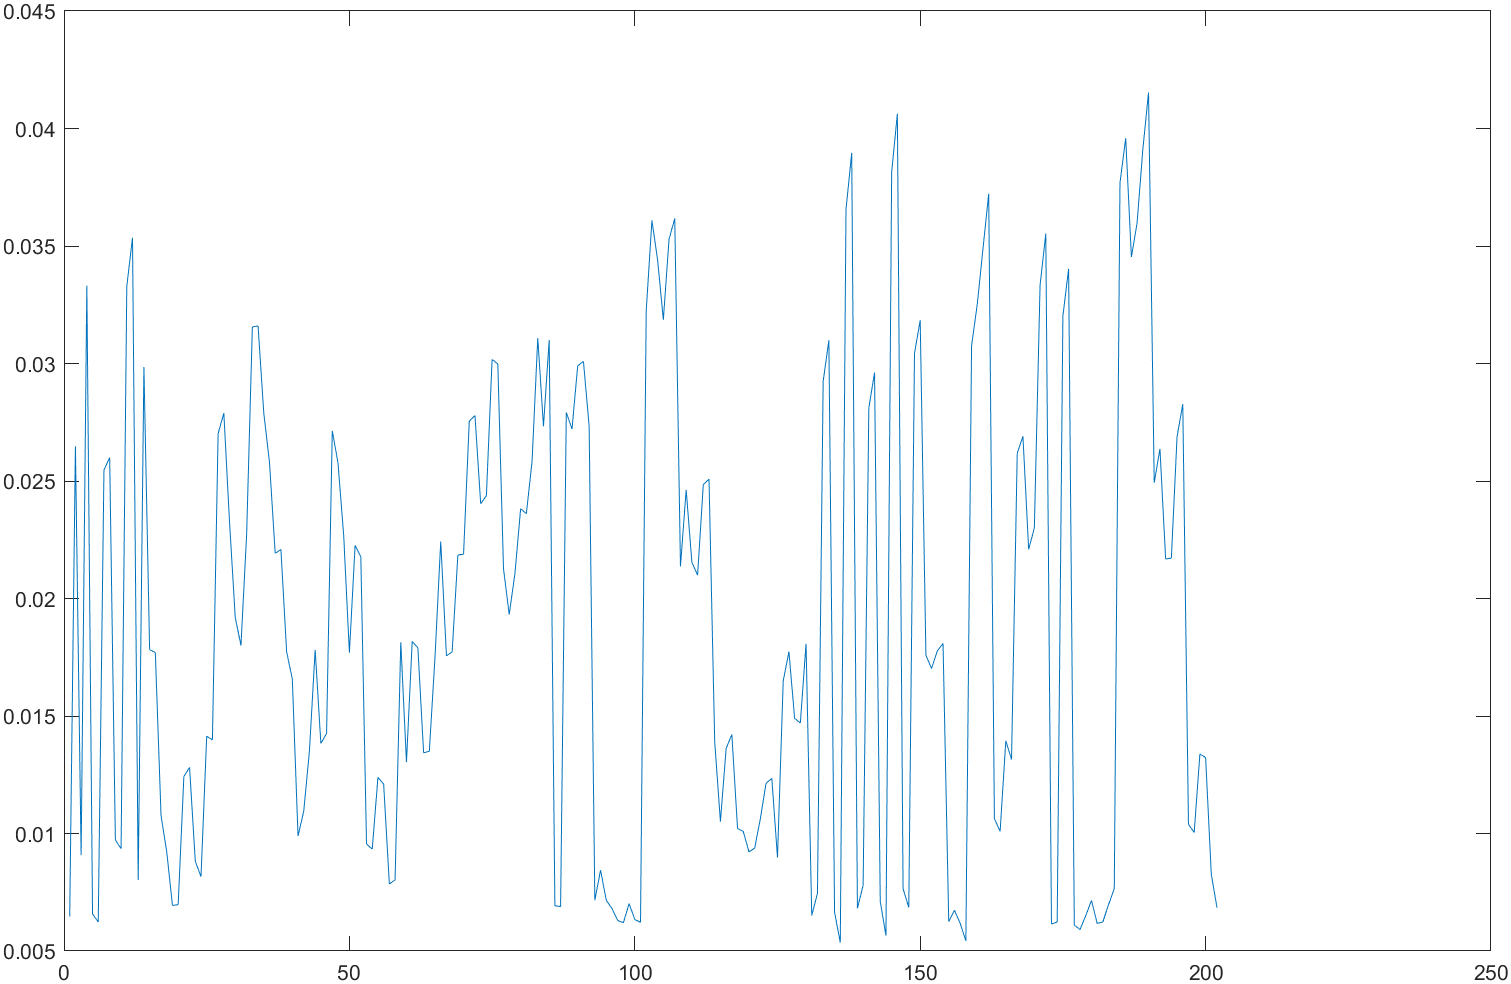

한 도체의 전체 element에 대한 기본파 분포가 이렇게 다양한데 어떤 B를 사용할것인가? 

평균? mean값? 최대값?, 식은 w,h가 없는데 어떤식?

이거를 사용하기 위한 가정은 [Taha]

The assumption of flux density $B$ uniform on conductor is equivalent to:


$$
$$d \ll \delta$$$



$$P_{\text {proximity }}=\frac{1}{T} \int\left(\frac{\pi \sigma l d^4}{64}\left(\frac{d B_r}{d t}\right)^2+\frac{\pi \sigma l d^4}{64}\left(\frac{d B_\theta}{d t}\right)^2\right) d t \\
P_{\text {proximity }}=\sum_{\text {th }}\left(\frac{\pi \sigma l d^4 B_{r, m}^2 \omega_i^2}{128}+\frac{\pi \sigma l d^4 B_{\theta i, m}^2 \omega_i^2}{128}\right)
$$


### Orthogonal Method (element별로 계산해서 더하기) -> J

[TAha] ICEM -> [1990ferreira] 

Total losses are expressed as follows [22]: (역시 B는 Uniform하다는 가정)


$$P=\frac{l}{\sigma} \int_{t=0}^T \int\int j^2 \cdot d S \cdot d t=\frac{l}{\sigma} \int_{t=0}^T \int\int\left(j_s+j_p\right)^2 \cdot d S \cdot d t$$



$$P=\frac{l}{\sigma} \int_{t=0}^T\left[\int\int\left(j_s+j_p\right)^2 d S+\int_{-\frac{d}{2}}^{\frac{d}{2}} \int_{-\frac{d}{2}}^{\frac{d}{2}} 2 \cdot j_s j_p \cdot d x \cdot d y\right] d t$$


J: element 는 입력밖에 없는데 어떻게 계산?

[22] [1990ferreira] 


$$\mathrm{P}_{\mathrm{u}}=\frac{1}{\mathrm{~T} \sigma} \int_{\mathrm{A}} \int_0^{\mathrm{T}}|\mathrm{J}(\mathrm{x}, \mathrm{y})|^2 \mathrm{dt} d \mathrm{~A}$$



$$\mathrm{P}_{\mathrm{u}}=\frac{1}{2 \sigma} \int_{\mathrm{A}}\left(\mathrm{J}_{\mathrm{s}}+\mathrm{J}_{\mathrm{p}}\right)\left(\mathrm{J}_{\mathrm{s}}{ }^*+\mathrm{J}_{\mathrm{p}}{ }^*\right) \mathrm{dA}$$


$\mathrm{P}_{\mathrm{u}}=\frac{1}{2 \sigma} \int_{\mathrm{A}}\left(\mathrm{J}_{\mathrm{s}} \mathrm{J}_{\mathrm{s}}^*+\mathrm{J}_{\mathrm{p}} \mathrm{J}_{\mathrm{p}}^*\right) \mathrm{d} \mathrm{A}$=$=\left(P_{u s}+P_{u p}\right)$


$$\mathrm{P}_{\mathrm{up}}=\mathrm{GH}_{\mathrm{e}}{ }^2$$


$\mathrm{G}=\frac{-2 \pi \gamma}{\sigma} \frac{\text { ber }_2 \gamma \text { ber }^{\prime} \gamma+\text { bei }_2 \gamma \text { ber' }^{\prime} \gamma}{\text { ber }^2 \gamma+\text { bei }^2 \gamma}$ (round)

$$\mathrm{G}=\frac{\frac{\sqrt{\pi}}{2} \mathrm{~d} \xi}{\sigma} \frac{\sinh \xi-\sin \xi}{\cosh \xi+\cos \xi}$$ (rectanguar ) 

아 여기서 나왔구나

A는 Node

4.고조파를 적게쓸수록 스텝수를 줄일수있음

+5.고조파확인을 통해 후처리로 

#### SooHwan


$$$\nabla \times \mathbf{E}_{\mathrm{e}}=-\frac{\partial \mathbf{B}}{\partial t}=-\frac{\partial(\nabla \times \mathbf{A})}{\partial t}$$$



$$\mathbf{J}_{\mathrm{e}}=\sigma \frac{\partial \mathbf{A}}{\partial t}$$


-> $\mathbf{J}_{\mathrm{e}}=\sigma \frac{\partial \mathbf{A}}{\partial t}=\sigma \sum_{i=1}^n N_i(x, y, z) \frac{d \mathbf{A}_i(t)}{d t}
$

#### [WIP] 한 주파수의 A에 대한 전체 요소 J합산 (Node별 A로 요소별 J)

% sigma
J_e = calcElementCurrentDensity(A_dot_e, elements, nodes, copperWinding_sigma);
J_f = calcElementCurrentDensity(A_dot_f, elements, nodes, copperWinding_sigma);




$$$W_{A C, a}(t)=\sum_{i=1}^n \frac{1}{\sigma}\left\{J_{e, i}^2-J_{f, i}^2\right\}(t) \cdot S_i \cdot L$$$


W_AC_a = calcHybridACLossSooHwan(J_e, J_f, S, L, sigma); % 도체별 

이거없이 AC Loss 포함(/미포함에 따른 Scale 효과(x)에 따른 시스템 민감도 비교

## 3. Maxwell

###  LabLink


%% 
% Paccompare=[6.777E-005 0.0003418 0.0008544 0.001612]
% TotalHybAcLoss=sum(Paccompare)
% 
% 
% % ACLossHighFrequencyScaling_Method
% % HybridAdjustmentFactor_ACLosses
% % 
% %%correctionFactor
% correctionFactor=7
% Pac./Paccompare
% (Pac/correctionFactor)./Paccompare
% PacScale=(Pac/correctionFactor)
% %%
% BFlux=[0.02997 0.07131 0.1159 0.1667]
% plot(BFlux)
% meanB=(BFlux/mean(BFlux))
% meanPaccom=(Paccompare/mean(Paccompare))
% meanPac=(Pac/mean(Pac))
% 
% PacScale
% % plot([1 2 3 4],[meanPaccom' meanPac'])
% plot([1 2 3 4],[Paccompare' PacScale'])

% plot([1 2 3 4],[meanB' meanPaccom' meanPac'])
    % Pac2(cIdx)      =   pi*(mm2m(la)*mm2m(Cuboid_Width)*(mm2m(Cuboid_Height))^3*sigma*(omegaE *B     )^2/divCoeffi) ;
    % m^5*[A/mV] * (V*s/m2 )^2  * omega
    % m^4/m^4 * [A/V]*[V^2*s^2] *2pi*f
    % AV*s^2